# Example 2: Analysis of an .stl file.

First, define the stl file and path for the file you wish to analyse

filepathname = "data/stls/3DBenchy.stl"; % Full path and name of the .stl file
mysurfaceMesh = surfaceMesh('stl',filepathname); % Create the surfaceMesh object from the .stl file

Calculate properties of the surfaceMesh object, define which method of curvature analysis you want to use.

"**none**" will produce the fastest result but have no curvature data - this is the default, and will be used for any other input.

"surfaceMesh" uses the surfaceMeshcurvature algorithm based on the paper:  Meyer, M., Desbrun, M., Schröder, P., & Barr, A. H. (2003). Discrete differential-geometry operators for triangulated 2-manifolds. Visualization and mathematics III (pp. 35-57). Springer Berlin Heidelberg. [http://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.24.3427&rep=rep1&type=pdf](http://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.24.3427&rep=rep1&type=pdf)

"**patch**" uses the patch curvature function, written by D.Kroon University of Twente (August 2011) . This is based on a fitting a quadratic patch around each local vertex and it's neighbouring vertices. This is typically slower than the surfaceMeshcurvature algorithm.

curvatureMethod = "none"; % Define which method of curvature analysis ("none", "surfaceMesh", "patch")
mysurfaceMesh = mysurfaceMesh.calculateProperties(curvatureMethod);
faceProperties = fieldnames(mysurfaceMesh.Fproperty)

faceProperties = 7×1 cell array
    {'Nx'         }
    {'Ny'         }
    {'Nz'         }
    {'inclination'}
    {'centroid'   }
    {'area'       }
    {'volume'     }


vertexProperties = fieldnames(mysurfaceMesh.Vproperty)

vertexProperties = 7×1 cell array
    {'Nx'         }
    {'Ny'         }
    {'Nz'         }
    {'inclination'}
    {'LPBFQuality'}
    {'Ra'         }
    {'Rz'         }


## Preview the a colored surfaceMesh

Define the **property** you wish to preview. You may use any per-face or per-vertex property within **mysurfaceMesh**, the names of these properties may be found as the fields of **mysurfaceMesh.Fproperty** or **mysurfaceMesh.Vproperty **

You may specify to use "**fancy**" graphics, which will be used be default if nothing is specified.

You may also wish to pass in an **Axis**, which the surfaceMesh will be plotted on - by default a new axis will be created for the figure.

By default, the colorbar automatically scales to capture the 1st-99th percentile data.

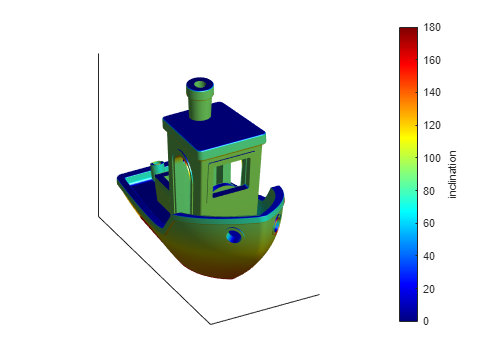

property = 'inclination'; % property name must match the string before the space character
opt.fancy = 1; % boolean 1 or 0 to turn fancy graphics on or off.
figure; ax = gca; % gca uses the current axis object
mysurfaceMesh.plotMesh(property,opt,ax);

## Convert to field data structure

Field based, or implicit data is an alternative way to define geometry. The TPMS designer package includes utilities to convert a surfaceMesh object to a **v3field** object which is a voxelised representation of the same geometry.

The user may define a voxel size, smaller numbers will result in higher computational cost, but better resolution.

If you wish to create properties, this can be done by modifying the **v3field.calculateProperties** function and saving the new properties under v3field.properties.

voxelSize = 0.5; %voxelsize in mm
myv3field=mysurfaceMesh.getField(voxelSize);
myv3field=myv3field.calculateProperties % Call the calculate properties method to fill out property data

myv3field =   v3Field with properties:

        name: "data/stls/3DBenchy.stl"
       lower: [0 0 0]
       upper: [60.0010 31.0040 48]
         res: [121 63 96]
          xq: [0 0.5000 1.0000 1.5000 2.0000 2.5000 3.0001 3.5001 4.0001 4.5001 5.0001 5.5001 6.0001 6.5001 7.0001 7.5001 8.0001 8.5001 9.0002 9.5002 10.0002 10.5002 11.0002 11.5002 12.0002 12.5002 13.0002 13.5002 14.0002 14.5002 15.0003 15.5003 … ]
          yq: [0 0.5001 1.0001 1.5002 2.0003 2.5003 3.0004 3.5005 4.0005 4.5006 5.0006 5.5007 6.0008 6.5008 7.0009 7.5010 8.0010 8.5011 9.0012 9.5012 10.0013 10.5014 11.0014 11.5015 12.0015 12.5016 13.0017 13.5017 14.0018 14.5019 15.0019 15.5020 … ]
          zq: [0 0.5053 1.0105 1.5158 2.0211 2.5263 3.0316 3.5368 4.0421 4.5474 5.0526 5.5579 6.0632 6.5684 7.0737 7.5789 8.0842 8.5895 9.0947 9.6000 10.1053 10.6105 11.1158 11.6211 12.1263 12.6316 13.1368 13.6421 14.1474 14.6526 15.1579 15.6632 … ]
    property: [1×1 struc

myv3field.property

ans = struct with fields:
                    X: [63×121×96 double]
                    Y: [63×121×96 double]
                    Z: [63×121×96 double]
              surface: [63×121×96 double]
                solid: [63×121×96 double]
                    U: [63×121×96 double]
              azimuth: [63×121×96 double]
          inclination: [63×121×96 double]
    manufacturability: [63×121×96 double]


## Preview and visualise field-based properties

Similarly to visualising property of a surfaceMesh, the user can visualise **v3field** properties.

You may specify a **sliceHeight** (as a percentage of the total object height) you with to preview the filed property at, this may be added/overlayed on previously made figures. Alternatively set **sliceHeight** = [] to utilise matlab's interactive orthosliceviewer.

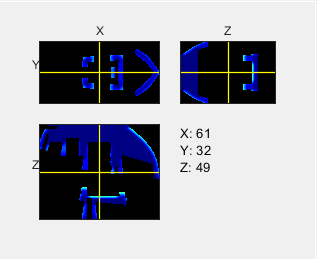

property = "manufacturability";
sliceHeight = []; 
h = myv3field.plotField(property,sliceHeight);

## Further Data Analysis

The distribution of various proeprties can also give inishgts into the performance of a component.

For example, we can look at the probability density distribution of the manufacturability index. The index is defined as -1=empty space, and solid volume ranging from 0 to 1 - where 0 is likely to fail/have problems and 1 being produced without problems.

A design which is more suited to additive manufacturing will have a distribution with a small fraction close to 0 (or volume requiring support structures).

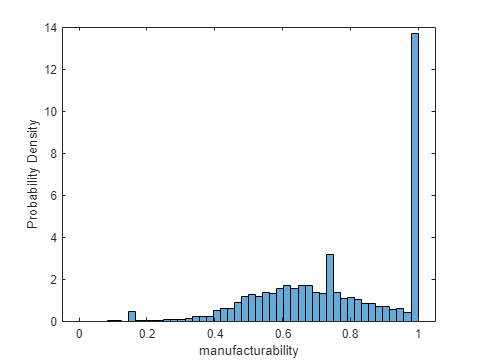

figure
temp = myv3field.property.manufacturability;
temp = temp(myv3field.property.surface==1);
histogram(temp,'BinLimits',[0 1],'Normalization',"pdf");
%set(gca, 'YScale', 'log'); grid on;
ylabel(gca,'Probability Density'); xlabel(gca,property);

## Using metrics

As the structures investigated are highly complex and are often unwieldy to asses, TPMS Designer utilises a metrics-based approach. This allows a property of a complex design to be approximated with a simplified metric - these are used heavily in **example3_DOE** to compare various properties of TPMS-like structure in a large design of experiments. 

The **metrics** class includes a predefined set of normalised sums, means, maximums or defined percentiles value of various properties, as well as some mechanical metrics for use in comparing cellular structures.

Different metrics may require different properties to be calculated for the field or surface-mesh based representation of an object.

M = metrics;
M = M.fvMetrics(mysurfaceMesh);
M = M.mechanicalMetrics(myv3field)

M =   metrics with properties:

           CPUtime: []
            Nfaces: 225154
            Nnodes: 675462
            volume: NaN
    volumeFraction: 0.2057
       surfaceArea: 9.4311e+03
      relativeArea: []
             rmsMC: []
             rmsGC: []
         thickness: 6.8907
      poreDiameter: 21.8807
           areaVar: 0.0280
          areaMean: 0.1990
           areaStd: 0.1673
           areaMin: 0.0146
           areaMax: 0.6075
    areaBelow30deg: 0.1736
        LpbfRa_Max: 41.5611
       LpbfRa_Mean: 5.4050
    LPBFerror_Mean: []
     LPBFerror_Max: []
           elastic: []
           poisson: []
             shear: []
    totalStiffness: []
        zenerRatio: []
         errorFlag: 0
